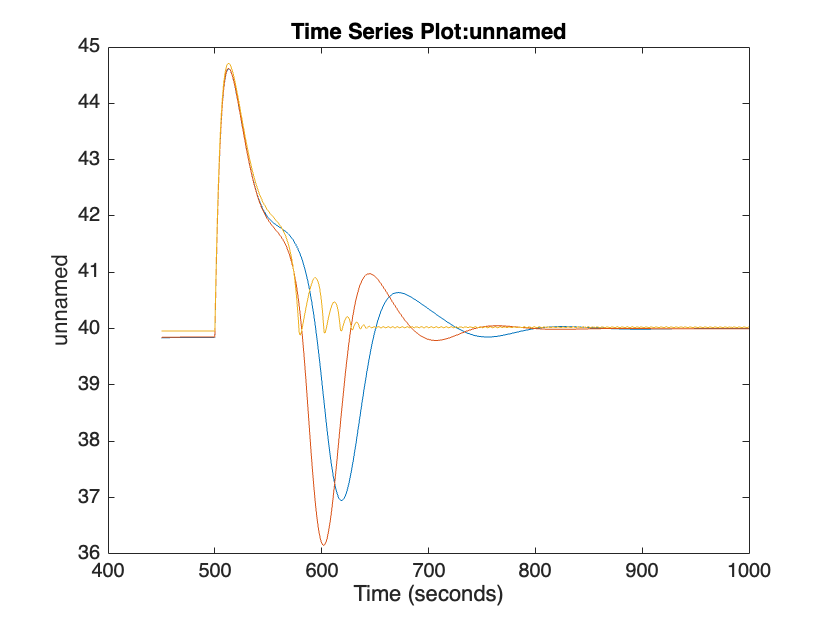

% PID

load_system("CSTR_Bioreactor_2023_FeedForward.slx");


set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "-0.025");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0");


set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(1));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(1));

set_param("CSTR_Bioreactor_2023_FeedForward/PID_glucose", "P", num2str(4));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_feedforward", "Value", num2str(1));
set_param("CSTR_Bioreactor_2023_FeedForward/feedforward_gain", "Gain", num2str(5000));


simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_ethanolconc)
hold on

% PI
load_system("CSTR_Bioreactor_2023_FeedForward.slx");


set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "-0.025");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0");


set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(2));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(2));

set_param("CSTR_Bioreactor_2023_FeedForward/PI_glucose", "P", num2str(6));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_feedforward", "Value", num2str(1));
set_param("CSTR_Bioreactor_2023_FeedForward/feedforward_gain", "Gain", num2str(5000));


simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_ethanolconc)
hold on

% P
load_system("CSTR_Bioreactor_2023_FeedForward.slx");


set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "-0.025");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0");


set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(3));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(3));

set_param("CSTR_Bioreactor_2023_FeedForward/P_glucose", "P", num2str(6757.725));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_feedforward", "Value", num2str(2));


simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_ethanolconc)
hold on

xline(500,"--")
legend("Manual PID with manual feedforward","Manual PI with manual feedforward","Cohen Coon P","Disturbance", "Location", "Best")
Plot();

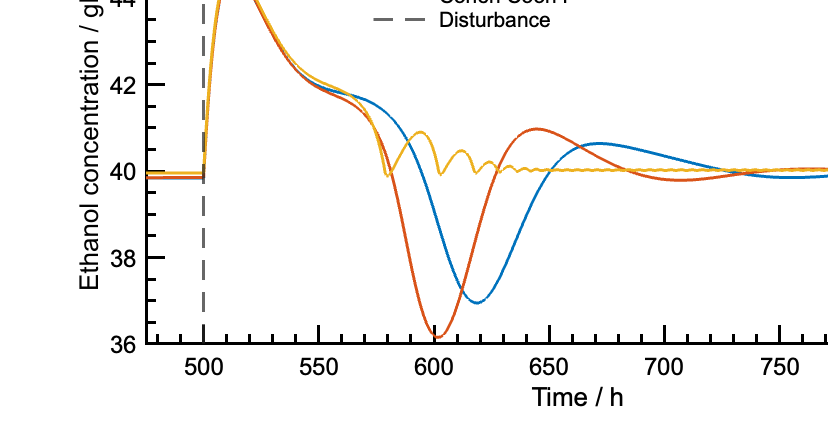

title("")
ylabel("Ethanol concentration / gL^{-1}")
xlabel("Time / h")
xlim([475,850])
exportgraphics(gcf,"figures/P_PI_PID_Comparison.pdf")